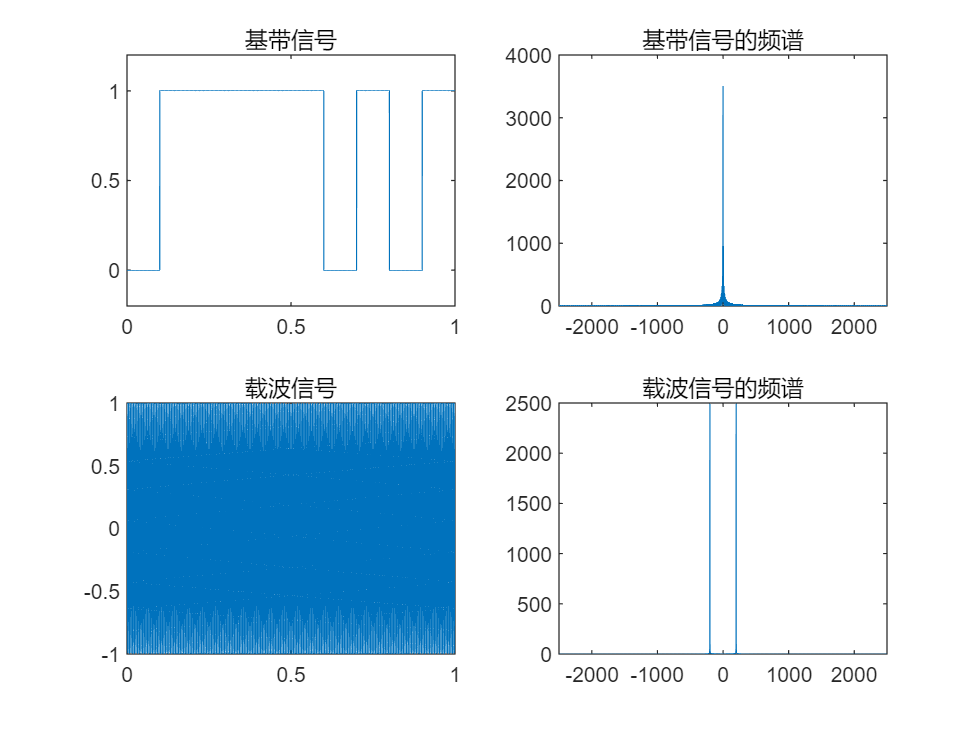

clc

close

a=round(rand(1,10));%产生10个码元

band=ones(1,500);%带宽为500

m=length(band);

N=length(a);

c=a(1)*band;

t0=1;

for i=1:N-1

c=[c,a(1+i)*band];

end

fc=200;

t=linspace(0,t0,N*m);

T=length(t);

w=(-T/2:T/2-1)./t0;

carri=cos(2*pi*fc*t);%载波信号

ask_modu=carri.*c;%调制

figure(1)

subplot(221);plot(t,c);title("基带信号");axis([0,1,-0.2,1.2]);

subplot(222);plot(w,abs(fftshift(fft(c))));title("基带信号的频谱");

subplot(223);plot(t,carri);title("载波信号");

subplot(224);plot(w,abs(fftshift(fft(carri))));title("载波信号的频谱");

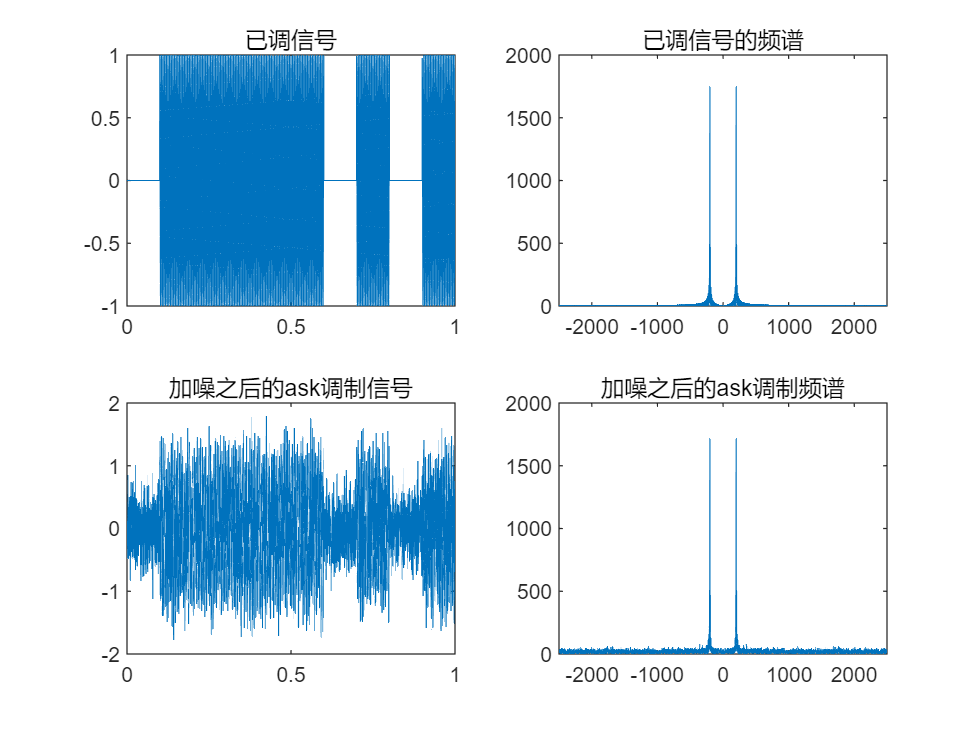

错误使用 axis>LocSetLimits
向量必须包含 4、6 或 8 个元素。

出错 axis (第 113 行)
                LocSetLimits(ax(j),cur_arg,names);


figure(2)

subplot(221);plot(t,ask_modu);title("已调信号");

subplot(222);plot(w,abs(fftshift(fft(ask_modu))));title("已调信号的频谱");

%信噪比10

snr=10;

ask_1=awgn(ask_modu,snr);

%解调

%经过带通滤波器

subplot(223);plot(t,ask_1);title('加噪之后的ask调制信号')

subplot(224);plot(w,abs(fftshift(fft(ask_1))));title('加噪之后的ask调制频谱')

fs=N*m;

fstop1=fc-100;

fstop2=fc+100;

fpass1=fc-20;

fpass2=fc+20;

band1=kais(fs,fstop1,fpass1,fpass2,fstop2);


b_2fsk1=filtfilt(band1,1,ask_1);

figure(3)

subplot(221);plot(t,b_2fsk1);title('经过带通滤波器之后的时域波形');

subplot(222);plot(w,abs(fftshift(fft(b_2fsk1))));title('经过带通滤波器之后的时域频谱');

%经过低通滤波器

fm=N;

at=b_2fsk1.*cos(2*pi*fc*t);

s_lpf1=lpf_kasi(fs,fm,2*fm);

s_lpf=filtfilt(s_lpf1,1,at);

subplot(223);plot(t,s_lpf);title('经过lpf之后的时域波形');

subplot(224);plot(w,abs(fftshift(fft(s_lpf))));title('经过lpf之后的频谱波形');

%抽样判决

szl=reshape(s_lpf,length(band),N);%重构数组，将1×5000的数组重构成500×10

for i=1:N

if szl(length(band)/2,i)>0.25

    szl(:,i)=1;

else

    szl(:,i)=0;

end

end

 szl=reshape(szl,[1,5000]);%重构数组，将500×10的数组重构成1×5000

figure(4)

subplot(221);plot(t,szl);axis([0,1,-0.2,1.2]);title('解调信号的时域波形');

subplot(222);plot(w,abs(fftshift(fft(szl))));title('解调信号的频域波形');